# Robot SCARA

clc; clear; close all;

%% ==========================================================
%  BLOQUE 1: ANÁLISIS SIMBÓLICO: ROBOT SCARA (RRP)
%  ==========================================================


=== ANÁLISIS SIMBÓLICO: ROBOT SCARA (RRP) ===


% Variables simbólicas 
syms q1 q2 d3 l1 l2 l3 beta1 beta2 real 

% --- 1. Eslabón 1 (Revoluta) ---
H1_0_sym = simplify( Hrz(q1) * Htz(l1+beta1) * Htx(l2) * round(Hrx(0)) );
disp(">>> Matriz H1_0:"); disp(H1_0_sym);

>>> Matriz H1_0:


$$\left(\begin{array}{cccc} \cos\left(q_{1}\right) & -\sin\left(q_{1}\right) & 0 & l_{2}\,\cos\left(q_{1}\right)\\ \sin\left(q_{1}\right) & \cos\left(q_{1}\right) & 0 & l_{2}\,\sin\left(q_{1}\right)\\ 0 & 0 & 1 & \beta_{1}+l_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$


% --- 2. Eslabón 2 (Revoluta) ---
H2_1_sym = simplify( Hrz(q2) * Htz(beta2) * Htx(l3) * round(Hrx(180)) );
H2_0_sym = simplify( H1_0_sym * H2_1_sym );
disp(">>> Matriz H2_0:"); disp(H2_0_sym);

>>> Matriz H2_0:


$$\left(\begin{array}{cccc} \cos\left(q_{1}+q_{2}\right) & \sin\left(q_{1}+q_{2}\right) & 0 & l_{3}\,\cos\left(q_{1}+q_{2}\right)+l_{2}\,\cos\left(q_{1}\right)\\ \sin\left(q_{1}+q_{2}\right) & -\cos\left(q_{1}+q_{2}\right) & 0 & l_{3}\,\sin\left(q_{1}+q_{2}\right)+l_{2}\,\sin\left(q_{1}\right)\\ 0 & 0 & -1 & \beta_{1}+\beta_{2}+l_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$


% --- 3. Eslabón 3 (Prismático) ---
H3_2_sym = simplify( Hrz(0) * Htz(d3) * Htx(0) * round(Hrx(0)) );
H3_0_sym = simplify( H2_0_sym * H3_2_sym );
Pf_sym = [H3_0_sym(1,4); H3_0_sym(2,4); H3_0_sym(3,4)];
disp(">>> Matriz Final H3_0:"); disp(H3_0_sym);

>>> Matriz Final H3_0:


$$\left(\begin{array}{cccc} \cos\left(q_{1}+q_{2}\right) & \sin\left(q_{1}+q_{2}\right) & 0 & l_{3}\,\cos\left(q_{1}+q_{2}\right)+l_{2}\,\cos\left(q_{1}\right)\\ \sin\left(q_{1}+q_{2}\right) & -\cos\left(q_{1}+q_{2}\right) & 0 & l_{3}\,\sin\left(q_{1}+q_{2}\right)+l_{2}\,\sin\left(q_{1}\right)\\ 0 & 0 & -1 & \beta_{1}+\beta_{2}-d_{3}+l_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$


% --- Cinemática Diferencial ---
disp("--- CINEMÁTICA DIFERENCIAL ---")

--- CINEMÁTICA DIFERENCIAL ---


J_sym = simplify(jacobian(Pf_sym, [q1, q2, d3]));
Det_J_sym = simplify(det(J_sym));
disp(">>> Matriz Jacobiana (3x3):"); disp(J_sym);

>>> Matriz Jacobiana (3x3):


$$\left(\begin{array}{ccc} -l_{3}\,\sin\left(q_{1}+q_{2}\right)-l_{2}\,\sin\left(q_{1}\right) & -l_{3}\,\sin\left(q_{1}+q_{2}\right) & 0\\ l_{3}\,\cos\left(q_{1}+q_{2}\right)+l_{2}\,\cos\left(q_{1}\right) & l_{3}\,\cos\left(q_{1}+q_{2}\right) & 0\\ 0 & 0 & -1 \end{array}\right)$$

disp(">>> Determinante de la Jacobiana:"); disp(Det_J_sym);

>>> Determinante de la Jacobiana:


$$-l_{2}\,l_{3}\,\sin\left(q_{2}\right)$$



%% ==================
%  BLOQUE 2: ROBOT 1 
%  ==================
disp("=== ROBOT 1: EVALUACIÓN Y GRÁFICAS ===")

=== ROBOT 1: EVALUACIÓN Y GRÁFICAS ===


% Parámetros exclusivos del Robot 1 SCARA
r1_l1 = 0.5; r1_l2 = 0.4; r1_l3 = 0.4;
r1_b1 = 0.1; r1_b2 = 0.1; 
r1_q1 = deg2rad(30); r1_q2 = deg2rad(45); r1_d3 = 0.3;

sym_vars = [q1, q2, d3, l1, l2, l3, beta1, beta2];
vals_R1  = [r1_q1, r1_q2, r1_d3, r1_l1, r1_l2, r1_l3, r1_b1, r1_b2];

% Evaluaciones Numéricas Robot 1
H1_R1 = double(subs(H1_0_sym, sym_vars, vals_R1)); S1_R1 = H1_R1(1:3, 4);
H2_R1 = double(subs(H2_0_sym, sym_vars, vals_R1)); S2_R1 = H2_R1(1:3, 4);
H3_R1 = double(subs(H3_0_sym, sym_vars, vals_R1)); Pf_R1 = H3_R1(1:3, 4);
P_Pilar_R1 = [0; 0; r1_l1 + r1_b1];

disp("Punto Final Pf_R1 (X, Y, Z):"); disp(Pf_R1');

Punto Final Pf_R1 (X, Y, Z):
    0.4499    0.5864    0.4000



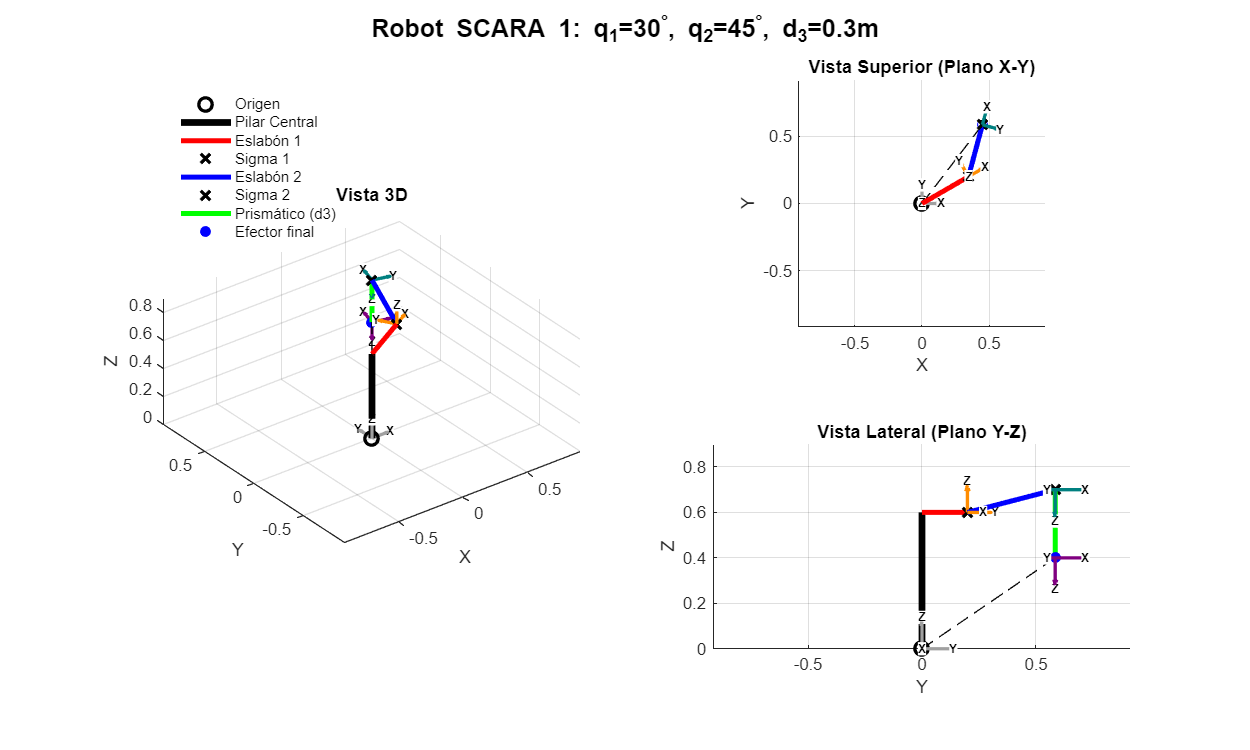


% --- Figura Robot----
L_max1 = r1_l2 + r1_l3; % Alcance radial máximo
figure('Name', 'Robot SCARA 1', 'Position', [50, 100, 1000, 600]);
sgtitle(['Robot SCARA 1: q_1=' num2str(rad2deg(r1_q1)) '^\circ, q_2=' num2str(rad2deg(r1_q2)) '^\circ, d_3=' num2str(r1_d3) 'm'], 'FontWeight', 'bold');

subplot(2, 2, [1, 3]);
h_leg = plotRobotSCARA(P_Pilar_R1, S1_R1, S2_R1, Pf_R1, H1_R1, H2_R1, H3_R1, L_max1);
view(3); title('Vista 3D');
legend([h_leg.orig, h_leg.e1v, h_leg.e1h, h_leg.s1, h_leg.e2, h_leg.s2, h_leg.e3, h_leg.pf], ...
       {'Origen', 'Pilar Central', 'Eslabón 1', 'Sigma 1', 'Eslabón 2', 'Sigma 2', 'Prismático (d3)', 'Efector final'}, ...
       'Location', 'Northwest','Box','off','FontSize',9);

subplot(2, 2, 2);
plotRobotSCARA(P_Pilar_R1, S1_R1, S2_R1, Pf_R1, H1_R1, H2_R1, H3_R1, L_max1);
view(0, 90); title('Vista Superior (Plano X-Y)');

subplot(2, 2, 4);
plotRobotSCARA(P_Pilar_R1, S1_R1, S2_R1, Pf_R1, H1_R1, H2_R1, H3_R1, L_max1);
view(90, 0); title('Vista Lateral (Plano Y-Z)');


% Cinemática Inversa Robot 1
[qi1, qi2, di3] = cinv_SCARA(r1_l1, r1_l2, r1_l3, r1_b1, r1_b2, Pf_R1(1), Pf_R1(2), Pf_R1(3));
disp("Cinemática Inversa R1 (q1, q2, d3):"); disp([qi1, qi2, di3]);

Cinemática Inversa R1 (q1, q2, d3):
   30.0000   45.0000    0.3000





%% ==========================================================
%  BLOQUE 3: ROBOT 2 (Movimientos en cuadrantes negativos)
%  ==========================================================
disp(" ")

disp("=== ROBOT 2: EVALUACIÓN Y GRÁFICAS ===")

=== ROBOT 2: EVALUACIÓN Y GRÁFICAS ===


r2_l1 = 0.6; r2_l2 = 0.5; r2_l3 = 0.3;
r2_b1 = 0.05; r2_b2 = 0.05; 
r2_q1 = deg2rad(-45); r2_q2 = deg2rad(90); r2_d3 = 0.4; % Eslabón prismático baja mucho

vals_R2  = [r2_q1, r2_q2, r2_d3, r2_l1, r2_l2, r2_l3, r2_b1, r2_b2];

H1_R2 = double(subs(H1_0_sym, sym_vars, vals_R2)); S1_R2 = H1_R2(1:3, 4);
H2_R2 = double(subs(H2_0_sym, sym_vars, vals_R2)); S2_R2 = H2_R2(1:3, 4);
H3_R2 = double(subs(H3_0_sym, sym_vars, vals_R2)); Pf_R2 = H3_R2(1:3, 4);
P_Pilar_R2 = [0; 0; r2_l1 + r2_b1]; 

disp("Punto Final Pf_R2 (X, Y, Z):"); disp(Pf_R2');

Punto Final Pf_R2 (X, Y, Z):
    0.5657   -0.1414    0.3000



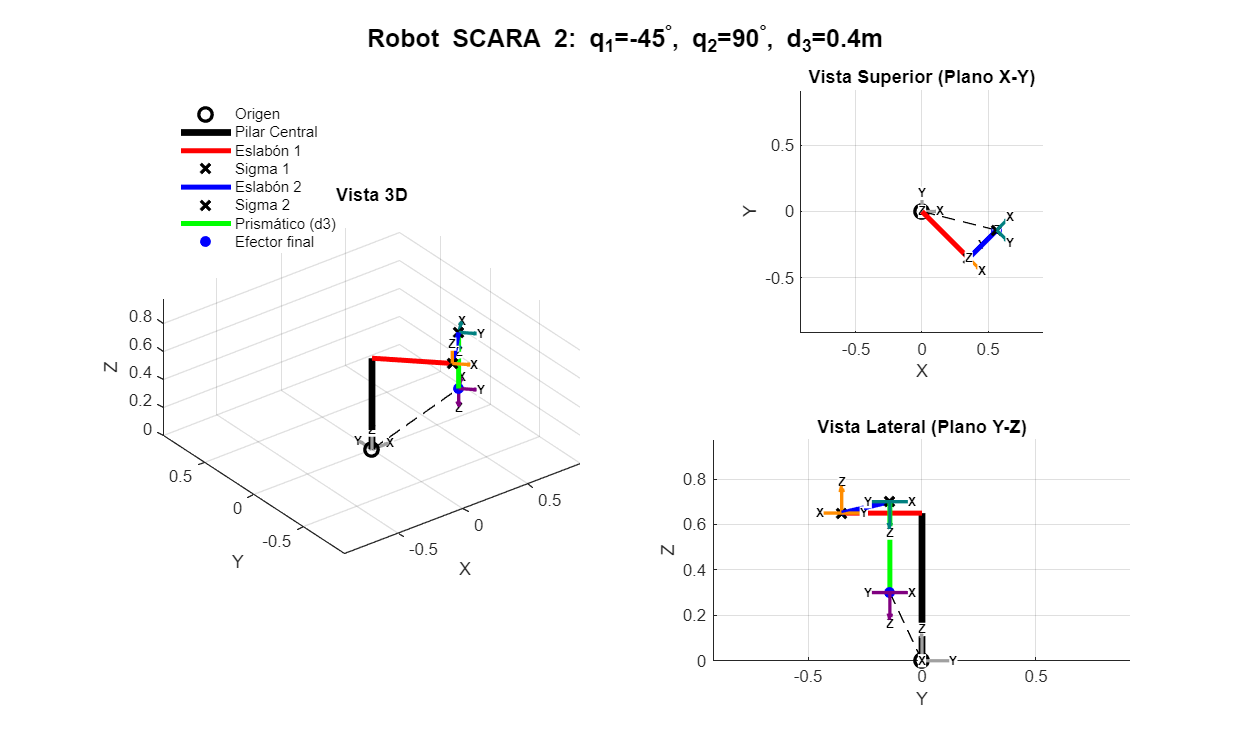


L_max2 = r2_l2 + r2_l3;
figure('Name', 'Robot SCARA 2', 'Position', [100, 150, 1000, 600]);
sgtitle(['Robot SCARA 2: q_1=' num2str(rad2deg(r2_q1)) '^\circ, q_2=' num2str(rad2deg(r2_q2)) '^\circ, d_3=' num2str(r2_d3) 'm'], 'FontWeight', 'bold');

subplot(2, 2, [1, 3]);
h_leg2 = plotRobotSCARA(P_Pilar_R2, S1_R2, S2_R2, Pf_R2, H1_R2, H2_R2, H3_R2, L_max2);
view(3); title('Vista 3D');
legend([h_leg2.orig, h_leg2.e1v, h_leg2.e1h, h_leg2.s1, h_leg2.e2, h_leg2.s2, h_leg2.e3, h_leg2.pf], ...
       {'Origen', 'Pilar Central', 'Eslabón 1', 'Sigma 1', 'Eslabón 2', 'Sigma 2', 'Prismático (d3)', 'Efector final'}, ...
       'Location', 'Northwest','Box','off','FontSize',9);

subplot(2, 2, 2);
plotRobotSCARA(P_Pilar_R2, S1_R2, S2_R2, Pf_R2, H1_R2, H2_R2, H3_R2, L_max2);
view(0, 90); title('Vista Superior (Plano X-Y)');

subplot(2, 2, 4);
plotRobotSCARA(P_Pilar_R2, S1_R2, S2_R2, Pf_R2, H1_R2, H2_R2, H3_R2, L_max2);
view(90, 0); title('Vista Lateral (Plano Y-Z)');


[qi1, qi2, di3] = cinv_SCARA(r2_l1, r2_l2, r2_l3, r2_b1, r2_b2, Pf_R2(1), Pf_R2(2), Pf_R2(3));
disp("Cinemática Inversa R2 (q1, q2, d3):"); disp([qi1, qi2, di3]);

Cinemática Inversa R2 (q1, q2, d3):
  -45.0000   90.0000    0.4000





%% ==========================================================
%  BLOQUE 4: ROBOT 3 (Eslabón prismático casi contraído)
%  ==========================================================
disp(" ")

disp("=== ROBOT 3: EVALUACIÓN Y GRÁFICAS ===")

=== ROBOT 3: EVALUACIÓN Y GRÁFICAS ===


r3_l1 = 0.4; r3_l2 = 0.6; r3_l3 = 0.6;
r3_b1 = 0; r3_b2 = 0; 
r3_q1 = deg2rad(120); r3_q2 = deg2rad(-60); r3_d3 = 0.05; 

vals_R3  = [r3_q1, r3_q2, r3_d3, r3_l1, r3_l2, r3_l3, r3_b1, r3_b2];

H1_R3 = double(subs(H1_0_sym, sym_vars, vals_R3)); S1_R3 = H1_R3(1:3, 4);
H2_R3 = double(subs(H2_0_sym, sym_vars, vals_R3)); S2_R3 = H2_R3(1:3, 4);
H3_R3 = double(subs(H3_0_sym, sym_vars, vals_R3)); Pf_R3 = H3_R3(1:3, 4);
P_Pilar_R3 = [0; 0; r3_l1 + r3_b1]; 

disp("Punto Final Pf_R3 (X, Y, Z):"); disp(Pf_R3');

Punto Final Pf_R3 (X, Y, Z):
         0    1.0392    0.3500



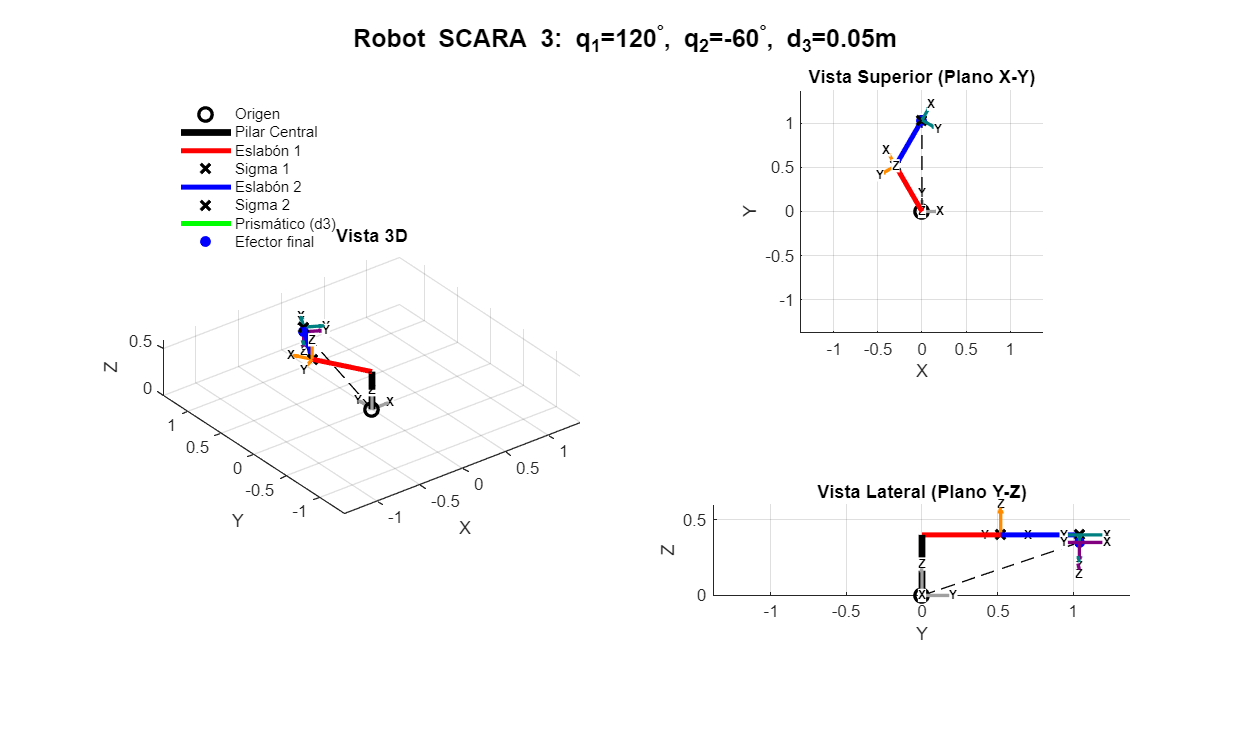


L_max3 = r3_l2 + r3_l3;
figure('Name', 'Robot SCARA 3', 'Position', [150, 200, 1000, 600]);
sgtitle(['Robot SCARA 3: q_1=' num2str(rad2deg(r3_q1)) '^\circ, q_2=' num2str(rad2deg(r3_q2)) '^\circ, d_3=' num2str(r3_d3) 'm'], 'FontWeight', 'bold');

subplot(2, 2, [1, 3]);
h_leg3 = plotRobotSCARA(P_Pilar_R3, S1_R3, S2_R3, Pf_R3, H1_R3, H2_R3, H3_R3, L_max3);
view(3); title('Vista 3D');
legend([h_leg3.orig, h_leg3.e1v, h_leg3.e1h, h_leg3.s1, h_leg3.e2, h_leg3.s2, h_leg3.e3, h_leg3.pf], ...
       {'Origen', 'Pilar Central', 'Eslabón 1', 'Sigma 1', 'Eslabón 2', 'Sigma 2', 'Prismático (d3)', 'Efector final'}, ...
       'Location', 'Northwest','Box','off','FontSize',9);

subplot(2, 2, 2);
plotRobotSCARA(P_Pilar_R3, S1_R3, S2_R3, Pf_R3, H1_R3, H2_R3, H3_R3, L_max3);
view(0, 90); title('Vista Superior (Plano X-Y)');

subplot(2, 2, 4);
plotRobotSCARA(P_Pilar_R3, S1_R3, S2_R3, Pf_R3, H1_R3, H2_R3, H3_R3, L_max3);
view(90, 0); title('Vista Lateral (Plano Y-Z)');


[qi1, qi2, di3] = cinv_SCARA(r3_l1, r3_l2, r3_l3, r3_b1, r3_b2, Pf_R3(1), Pf_R3(2), Pf_R3(3));
disp("Cinemática Inversa R3 (q1, q2, d3):"); disp([qi1, qi2, di3]);

Cinemática Inversa R3 (q1, q2, d3):
   60.0000   60.0000    0.0500





%% ==========================================================
%  FUNCION LOCAL DE GRAFICACIÓN SCARA
%  ==========================================================

function h = plotRobotSCARA(P_Pilar, S1, S2, Pf, H1, H2, H3, L_max)
    hold on; grid on; axis equal;
    
    % Componentes físicos del SCARA
    h.orig = plot3(0, 0, 0, 'ko', 'MarkerSize', 8, 'LineWidth', 2);
    
    % Pilar Central (Sube en Z hasta l1+b1)
    h.e1v  = plot3([0, P_Pilar(1)], [0, P_Pilar(2)], [0, P_Pilar(3)], 'k', 'LineWidth', 4); 
    
    % Eslabón 1 (Plano XY)
    h.e1h  = plot3([P_Pilar(1), S1(1)], [P_Pilar(2), S1(2)], [P_Pilar(3), S1(3)], 'r', 'LineWidth', 3);
    h.s1   = plot3(S1(1), S1(2), S1(3), 'kx', 'MarkerSize', 8, 'LineWidth', 2);
    
    % Eslabón 2 (Plano XY)
    h.e2   = plot3([S1(1), S2(1)], [S1(2), S2(2)], [S1(3), S2(3)], 'b', 'LineWidth', 3);
    h.s2   = plot3(S2(1), S2(2), S2(3), 'kx', 'MarkerSize', 8, 'LineWidth', 2);
    
    % Eslabón 3 Prismático (Baja en Z)
    h.e3   = plot3([S2(1), Pf(1)], [S2(2), Pf(2)], [S2(3), Pf(3)], 'g', 'LineWidth', 3); 
    h.pf   = plot3(Pf(1), Pf(2), Pf(3), 'bo', 'MarkerFaceColor', 'b');
    
    % Línea punteada de origen a punta
    plot3([0, Pf(1)], [0, Pf(2)], [0, Pf(3)], 'k--'); 
    
    % Límites dinámicos ajustados a la morfología SCARA
    lim_xy = L_max * 1.15; 
    lim_z  = P_Pilar(3) * 1.5; 
    xlim([-lim_xy, lim_xy]); ylim([-lim_xy, lim_xy]); zlim([0, lim_z]); 
    
    % Sistemas de Referencia
    scale = L_max * 0.15; 
    q0 = drawFrame(eye(4), scale); q0.Color = '#A0A0A0';
    q1 = drawFrame(H1, scale);     q1.Color = '#FF8C00';
    q2 = drawFrame(H2, scale);     q2.Color = '#008080';
    q3 = drawFrame(H3, scale);     q3.Color = '#800080';
    
    xlabel('X'); ylabel('Y'); zlabel('Z');
end